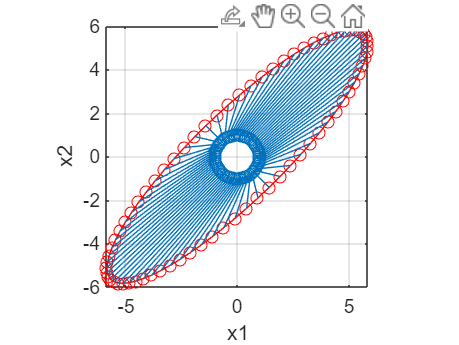

clear all; close all;

the=0:5:360;
x1=cosd(the); % 변경 전
x2=sind(the);
x=[x1; x2];

figure(1); clf;
plot(x1,x2,'o-');
axis square; grid on;
xlabel('x1'); ylabel('x2');

A=[5 3;3 5]; % Transfrom Matrix
y=A*x; % 변경 후
y1=y(1,:); 
y2=y(2,:);

hold on;
plot(y1,y2,'o-r');
for i=1:length(the)
    line([x1(i) y1(i)],[x2(i) y2(i)]);
end